% Template for MXB201 Project Part II.

## Initialisation

clear
d = dir('faces/*.pgm');
N = length(d);
I = imread([d(1).folder, '/', d(1).name]);
[rows,cols] = size(I);
M = rows*cols;
A = zeros(M, N)  % big matrix, whose columns are the images

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

## Read images as columns of the matrix

for j = 1:N
    I = imread([d(j).folder, '/', d(j).name]);
    A(:,j) = I(:);
end

## Calculate and visualise mean face

MeanA = mean(A, 2)

MeanA =    57.5760
   58.1640
   58.5980
   58.5510
   58.3900
   58.6100
   59.0360
   59.4340
   59.5230
   58.9780


ReA = reshape(MeanA, [rows, cols])

ReA =    57.5760   59.4170   61.4650   63.1940   65.0070   66.8300   68.3390   69.7030   70.7470   71.8870   73.6050   74.6290   75.9410   77.7020   79.6740   81.4520   82.8200   84.5660   86.2880   87.7410   89.0480   90.4460   91.7250   93.1100   94.6080   95.8420   97.3930   98.7770  100.5460  102.6270  104.5490  106.3050  108.1540  110.1540  112.2690  114.2730  116.1280  117.8940  119.7360  121.5340  122.7850  124.1210  125.2990  126.4440  127.8940  129.3370  130.7120  132.3970  134.1730  135.3890
   58.1640   59.9050   61.5370   63.3480   65.2380   67.0280   68.8080   70.0200   70.7510   71.6750   73.2280   74.4960   76.0340   77.5720   79.2630   80.9040   82.5630   84.3810   85.9100   87.1990   88.3310   89.7760   91.3770   92.9570   94.3790   95.4590   96.8410   98.4430  100.1610  102.2440  104.0760  105.9140  107.9790  110.1140  112.4440  114.5740  116.4810  118.0180  119.6820  121.1090  122.5440  124.3810  125.6010  126.7170  128.1720  129.6370  130.8990  132.2640  133.6470  1

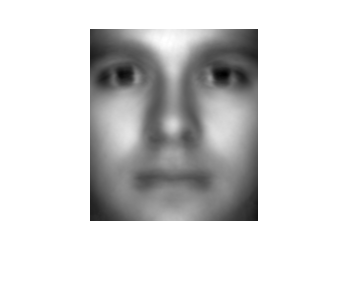

I =   Image with properties:

           CData: [192×168 double]
    CDataMapping: 'scaled'

  Show all properties


I = imshow(ReA, [])

## Calculate mean-centred SVD

MCA = A - MeanA

MCA =    22.4240   36.4240    1.4240   11.4240   -4.5760   48.4240   36.4240   61.4240   32.4240   61.4240   65.4240   46.4240   10.4240   41.4240  110.4240   99.4240   60.4240   15.4240   16.4240    7.4240  -10.5760   12.4240   -4.5760   -9.5760  -39.5760  -23.5760  -40.5760  -45.5760  -48.5760   28.4240   38.4240   39.4240    9.4240  -15.5760   44.4240   33.4240   52.4240   32.4240   62.4240   63.4240   36.4240    8.4240   54.4240   87.4240   89.4240   51.4240   12.4240   15.4240    8.4240  -10.5760
   22.8360   28.8360    8.8360    8.8360   -6.1640   43.8360   33.8360   59.8360   31.8360   57.8360   61.8360   45.8360   10.8360   39.8360   98.8360   96.8360   59.8360   10.8360   13.8360    3.8360   -9.1640    6.8360  -10.1640  -12.1640  -38.1640  -25.1640  -43.1640  -48.1640  -49.1640   20.8360   37.8360   36.8360    6.8360  -18.1640   43.8360   32.8360   51.8360   23.8360   56.8360   57.8360  -35.1640    6.8360  110.8360   85.8360   87.8360   53.8360   11.8360   12.8360    7.8360  -

[U,Sigma,V] = svd(MCA, 'econ')

U =     0.0047   -0.0063   -0.0008   -0.0030   -0.0074    0.0077    0.0020   -0.0010   -0.0099    0.0024   -0.0019    0.0029   -0.0035   -0.0023   -0.0002   -0.0048   -0.0044   -0.0044    0.0006    0.0049   -0.0004   -0.0082    0.0075   -0.0013   -0.0003    0.0060    0.0014    0.0019    0.0111   -0.0007   -0.0008   -0.0043    0.0087    0.0000   -0.0061    0.0079    0.0051    0.0015   -0.0017    0.0079    0.0058   -0.0012    0.0107    0.0082    0.0010   -0.0022   -0.0019   -0.0090   -0.0008    0.0035
    0.0048   -0.0064   -0.0008   -0.0029   -0.0075    0.0078    0.0016   -0.0006   -0.0097    0.0023   -0.0011    0.0025   -0.0042   -0.0031   -0.0004   -0.0043   -0.0045   -0.0043    0.0002    0.0056   -0.0006   -0.0078    0.0066   -0.0016    0.0003    0.0049    0.0016    0.0009    0.0117   -0.0015   -0.0006   -0.0033    0.0079   -0.0007   -0.0053    0.0081    0.0041    0.0011   -0.0014    0.0081    0.0044   -0.0012    0.0104    0.0074    0.0008   -0.0007   -0.0012   -0.0112   -0.0013    0

Sigma = 1.0e+05 *

    1.4981         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.3162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

V =    -0.0087   -0.0214    0.0011   -0.0223    0.0024   -0.0094    0.0142    0.0088   -0.0064    0.0314   -0.0194    0.0301   -0.0155    0.0448   -0.0067    0.0646   -0.0084    0.0029    0.0146   -0.0214    0.0652   -0.0336    0.0181   -0.0004    0.0173   -0.0217    0.0065   -0.0371    0.0130   -0.0098    0.0131   -0.0082    0.0287   -0.0071    0.0108   -0.0073    0.0195    0.0602   -0.0282    0.0090   -0.0286   -0.0045    0.0272    0.0057    0.0194   -0.0164    0.0036    0.0077    0.0084    0.0037
   -0.0115   -0.0273   -0.0359   -0.0185    0.0066   -0.0085    0.0048    0.0066   -0.0342    0.0259   -0.0183    0.0353   -0.0051    0.0365    0.0047    0.0559   -0.0265    0.0015    0.0072   -0.0085    0.0952   -0.0342    0.0239    0.0396    0.0230   -0.0092    0.0222   -0.0401    0.0105   -0.0245   -0.0140   -0.0307    0.0168   -0.0464   -0.0068   -0.0286    0.0089    0.0536   -0.0243    0.0103   -0.0305    0.0021    0.0194   -0.0032    0.0101    0.0001    0.0169   -0.0045   -0.0108    0

sigma = diag(Sigma)

sigma = 1.0e+05 *

    1.4981
    1.3162
    0.8023
    0.5178
    0.4554
    0.4080
    0.3869
    0.3534
    0.2989
    0.2900


## Visualise first 20 eigenfaces

NewU = U(:,1:20)

ans =     0.0047   -0.0063   -0.0008   -0.0030   -0.0074    0.0077    0.0020   -0.0010   -0.0099    0.0024   -0.0019    0.0029   -0.0035   -0.0023   -0.0002   -0.0048   -0.0044   -0.0044    0.0006    0.0049
    0.0048   -0.0064   -0.0008   -0.0029   -0.0075    0.0078    0.0016   -0.0006   -0.0097    0.0023   -0.0011    0.0025   -0.0042   -0.0031   -0.0004   -0.0043   -0.0045   -0.0043    0.0002    0.0056
    0.0048   -0.0063   -0.0009   -0.0031   -0.0077    0.0076    0.0015   -0.0002   -0.0091    0.0024   -0.0001    0.0027   -0.0048   -0.0030   -0.0009   -0.0033   -0.0044   -0.0041   -0.0007    0.0067
    0.0048   -0.0063   -0.0010   -0.0034   -0.0081    0.0070    0.0015   -0.0004   -0.0086    0.0025    0.0010    0.0029   -0.0059   -0.0030   -0.0012   -0.0024   -0.0039   -0.0039   -0.0015    0.0070
    0.0048   -0.0062   -0.0011   -0.0036   -0.0080    0.0062    0.0013   -0.0006   -0.0084    0.0029    0.0017    0.0028   -0.0066   -0.0027   -0.0012   -0.0017   -0.0037   -0.0037   -0.0016

NewU1 = NewU1()

## Calculate coordinate vectors

## Demonstrate rudimentary moustache detector